# Generate a scene from an typical image (RGB) file.

This tutorial generates ISET scenes from RGB file on different displays. It also shows the three different display gamuts as well as approximate renderings of the images.

See also: s_sceneFromRGB, displayCreate

Copyright Imageval Consulting, LLC, 2014

ieInit;

## Create scene from file

imgFileName = 'macbeth.tif';
dispOLEDFile = 'OLED-Sony.mat';
dispLCDFile = 'LCD-Apple.mat';
dispCRTFile = 'CRT-Dell.mat';

## Create scene from file for OLED

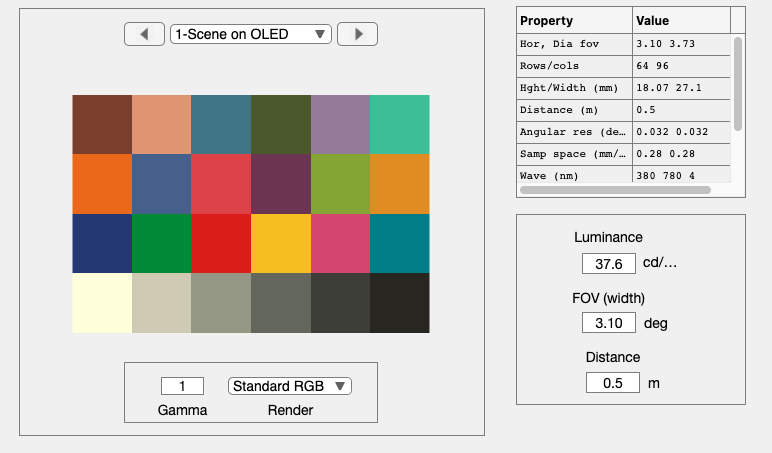

% The illuminant is set to be the white point of the monitor
sceneA = sceneFromFile(imgFileName,'rgb',[],dispOLEDFile);
sceneA = sceneSet(sceneA,'name','Scene on OLED');
ieAddObject(sceneA); sceneWindow;

## Show scene on LCD

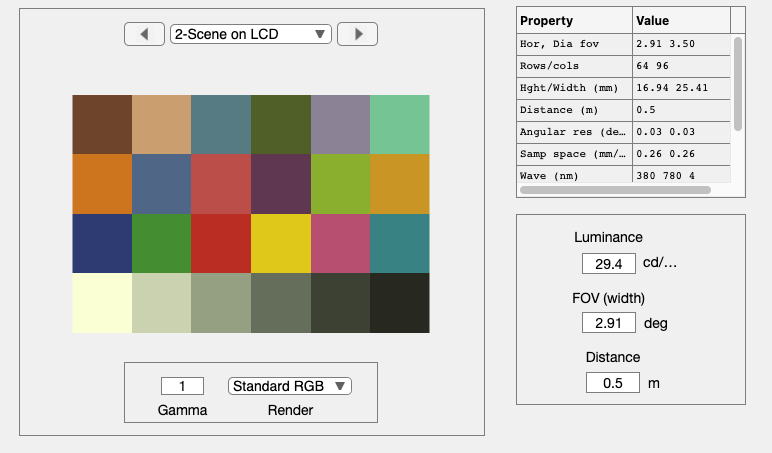

sceneB = sceneFromFile(imgFileName,'rgb',[],dispLCDFile);
sceneB = sceneSet(sceneB,'name','Scene on LCD');
ieAddObject(sceneB); sceneWindow;

## Show scene on CRT

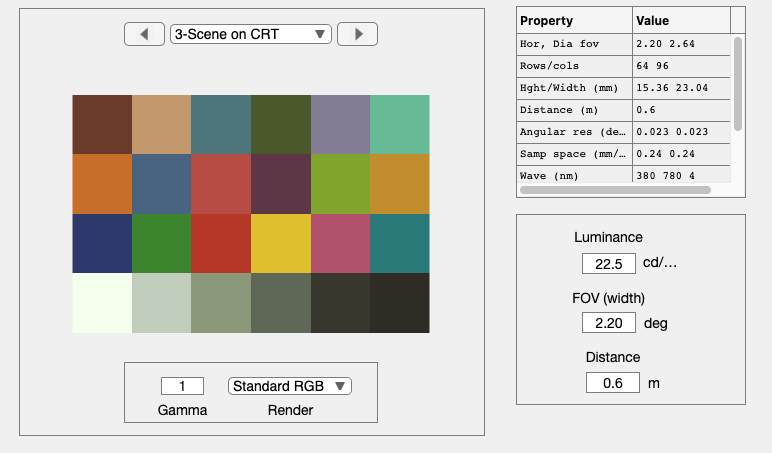

sceneC = sceneFromFile(imgFileName,'rgb',[],dispCRTFile);
sceneC = sceneSet(sceneC,'name','Scene on CRT');
ieAddObject(sceneC); sceneWindow;

## Compare the three images

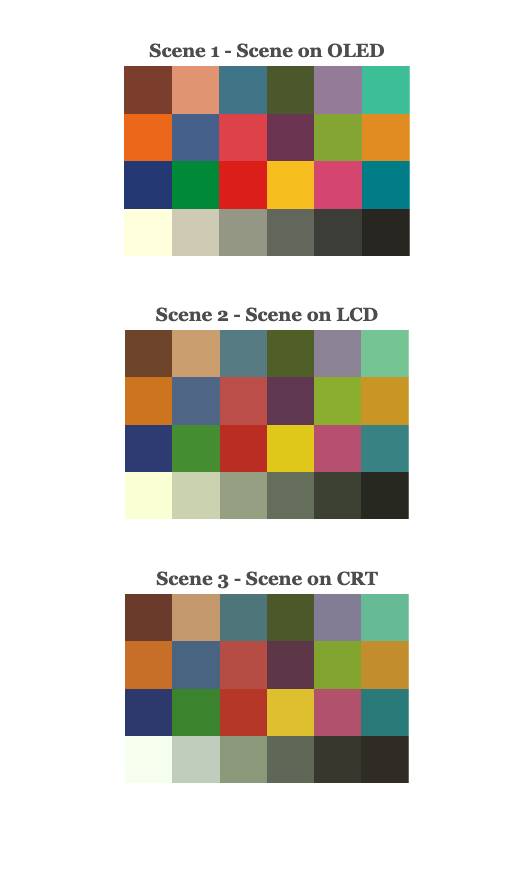

imageMultiview('scene', 1:3, true);

## Compare the gamuts of the three monitors

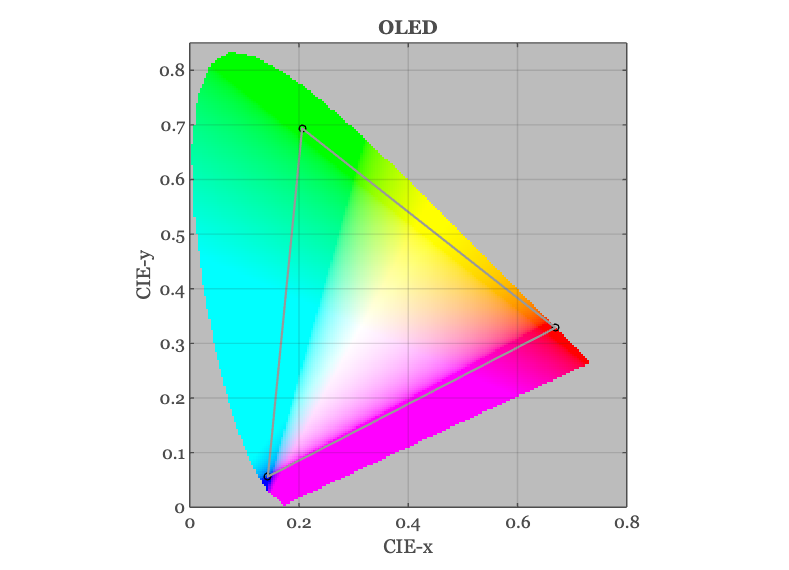

d = displayCreate(dispOLEDFile);
displayPlot(d,'gamut');
title('OLED')

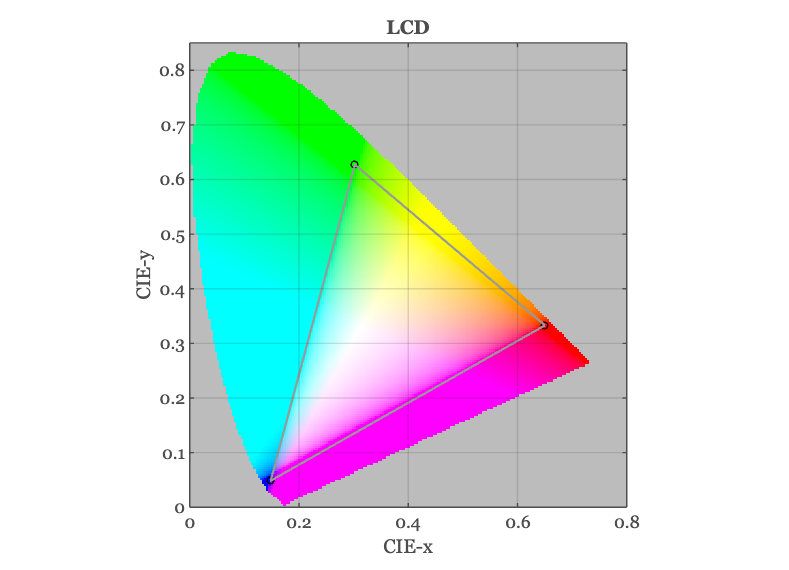


d = displayCreate(dispLCDFile);
displayPlot(d,'gamut');
title('LCD')

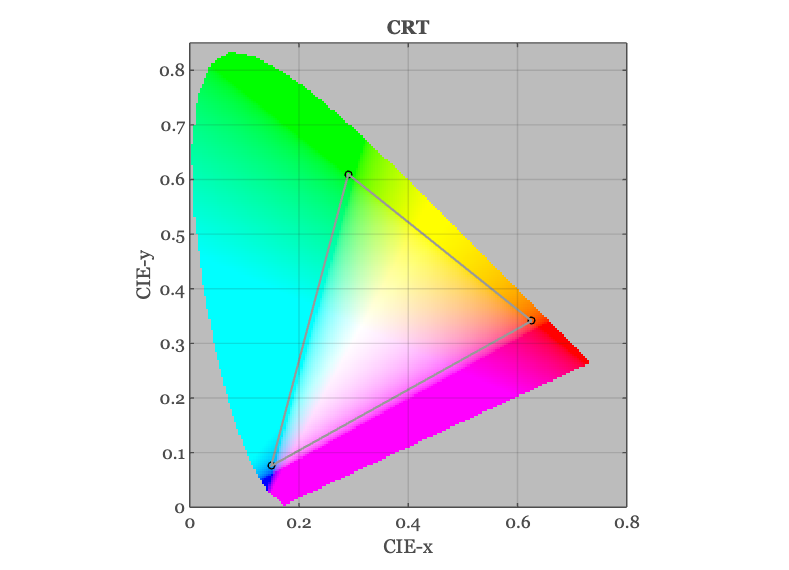


d = displayCreate(dispCRTFile);
displayPlot(d,'gamut');
title('CRT')